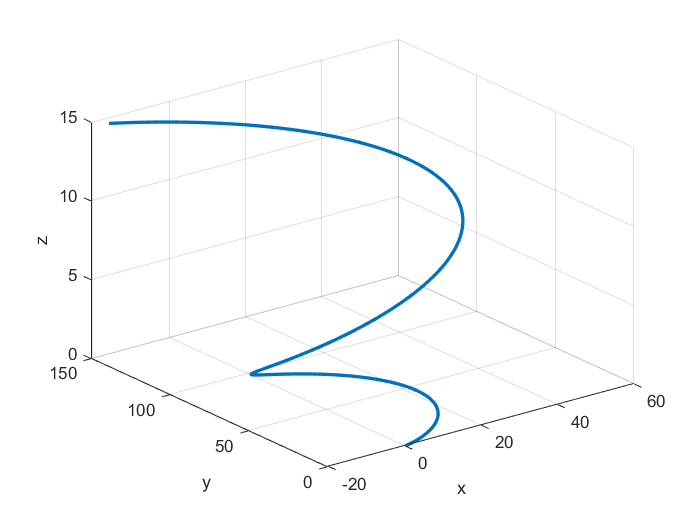

R_0 = [0; 0; 0];
V_0 = [0; 0; 0];
t = linspace(0, 20, 200);
A = [5 * cos(t/2); 5 * sin(t/2); 0.1 * ones(size(t/2))]; % Erhöhte Beschleunigung
V = cumtrapz(t/2, A, 2) + V_0;

R = R_0 + cumtrapz(t/2, V, 2) + 0.5 * cumtrapz(t/2, A, 2) .* t;
figure;
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;



%R_measured = radar_messured(R);
R_measured = [];

% Loop durch das Array, springen Sie in Schritten von 10 (5 behalten, 5 verwerfen)
for i = 1:10:length(R)
    % Fügen Sie die ersten 5 Elemente von jedem Block von 10 hinzu
    R_measured = [R_measured R(:,i:min(i+4, end))];
    
end

R_measured

R_measured =          0    0.0189    0.0756    0.1699    0.3012    1.8277    2.1951    2.5911    3.0139    3.4617    6.5599    7.1237    7.6945    8.2699    8.8472   12.2030   12.7195   13.2169   13.6926   14.1442   16.2176   16.4377   16.6171   16.7541   16.8475   16.4291   16.1896   15.9008   15.5626   15.1754   11.8577   11.1488   10.3992    9.6108    8.7855    3.1897    2.1744    1.1433    0.0994   -0.9539   -7.2818   -8.3051   -9.3098  -10.2926  -11.2497  -16.2617  -16.9444  -17.5752  -18.1513  -18.6699
         0    0.0005    0.0035    0.0116    0.0272    0.4155    0.5506    0.7117    0.9004    1.1187    3.1358    3.6015    4.1068    4.6521    5.2380    9.6079   10.4758   11.3819   12.3250   13.3040   19.8459   21.0303   22.2359   23.4603   24.7009   32.3359   33.6137   34.8851   36.1471   37.3967   44.4655   45.5449   46.5886   47.5939   48.5584   53.3595   53.9769   54.5376   55.0403   55.4841   56.8673   56.8823   56.8362   56.7297   56.5636   54.3896   53.8475   53.2599   52.

% Angenommen, Ihr Array heißt 'data'
data = rand(3,200); % Hier generieren wir ein Beispiel-Array mit 200 Werten.

% Initialisieren Sie das neue Array
neuesArray = [];

% Loop durch das Array, springen Sie in Schritten von 10 (5 behalten, 5 verwerfen)
for i = 1:10:length(data)
    % Fügen Sie die ersten 5 Elemente von jedem Block von 10 hinzu
    neuesArray = [neuesArray data(:,i:min(i+4, end))];
end

neuesArray

neuesArray =     0.1880    0.6310    0.6415    0.1249    0.9301    0.0149    0.8087    0.4560    0.0253    0.5489    0.6899    0.0374    0.4858    0.7597    0.7593    0.2917    0.7746    0.2538    0.2315    0.5006    0.8022    0.0146    0.6542    0.8873    0.7137    0.6763    0.8371    0.5837    0.5546    0.5253    0.3551    0.2025    0.5132    0.8925    0.7881    0.6775    0.7575    0.4111    0.0149    0.2005    0.2812    0.8720    0.6092    0.0158    0.4318    0.8665    0.2196    0.8595    0.5828    0.0093
    0.6678    0.4682    0.5620    0.6740    0.8288    0.1422    0.0471    0.8030    0.2186    0.8697    0.2344    0.6634    0.8617    0.2467    0.5862    0.2455    0.8227    0.8005    0.3811    0.5406    0.6715    0.7632    0.6347    0.6659    0.4472    0.6485    0.7273    0.9209    0.9308    0.1267    0.5478    0.6438    0.5698    0.8332    0.3736    0.9876    0.2751    0.2166    0.0433    0.7194    0.8201    0.2680    0.0180    0.6839    0.6313    0.9805    0.5182    0.2600    0.

function [new_array1, new_array2, new_array3] = radar_messured(R)
    writeColumns = 5; % Anzahl der hintereinander zu schreibenden Spalten
    skipColumns = 5; % Anzahl der zu überspringenden Spalten
    new_array = [];
    [~, cols] = size(R);
    
    for col = 1:skipColumns:cols-writeColumns+1
        new_array1 = [new_array, R(1, col:col+writeColumns-1)];
        new_array2 = [new_array, R(2, col:col+writeColumns-1)];
        new_array3 = [new_array, R(3, col:col+writeColumns-1)];
    end
end